set(groot,'defaultLegendInterpreter','latex');
set(groot,'defaultTextInterpreter','latex');


rng(123); 

N = 500000; 
dt = 0.001; 

x_truth = zeros(1,N);
y_truth = zeros(1,N);
z_truth = zeros(1,N);

g_truth = 1;
b_truth = 4;
a_truth = 1/4;
f_truth = 8;

sigma_x_truth = .1;
sigma_y_truth = .1;
sigma_z_truth = .1;

m_ens = 50;

for i = 2:N
    x_truth(i) = x_truth(i-1) + ( - (y_truth(i-1)^2 + z_truth(i-1)^2) - a_truth * (x_truth(i-1) - f_truth)) * dt + sigma_x_truth * randn * sqrt(dt);
    y_truth(i) = y_truth(i-1) + ( - b_truth * x_truth(i-1) * z_truth(i-1) + x_truth(i-1) * y_truth(i-1) - y_truth(i-1) + g_truth) * dt + sigma_y_truth * randn * sqrt(dt);
    z_truth(i) = z_truth(i-1) + ( b_truth * x_truth(i-1) * y_truth(i-1) + x_truth(i-1) * z_truth(i-1) - z_truth(i-1)) * dt + sigma_z_truth * randn * sqrt(dt);
end

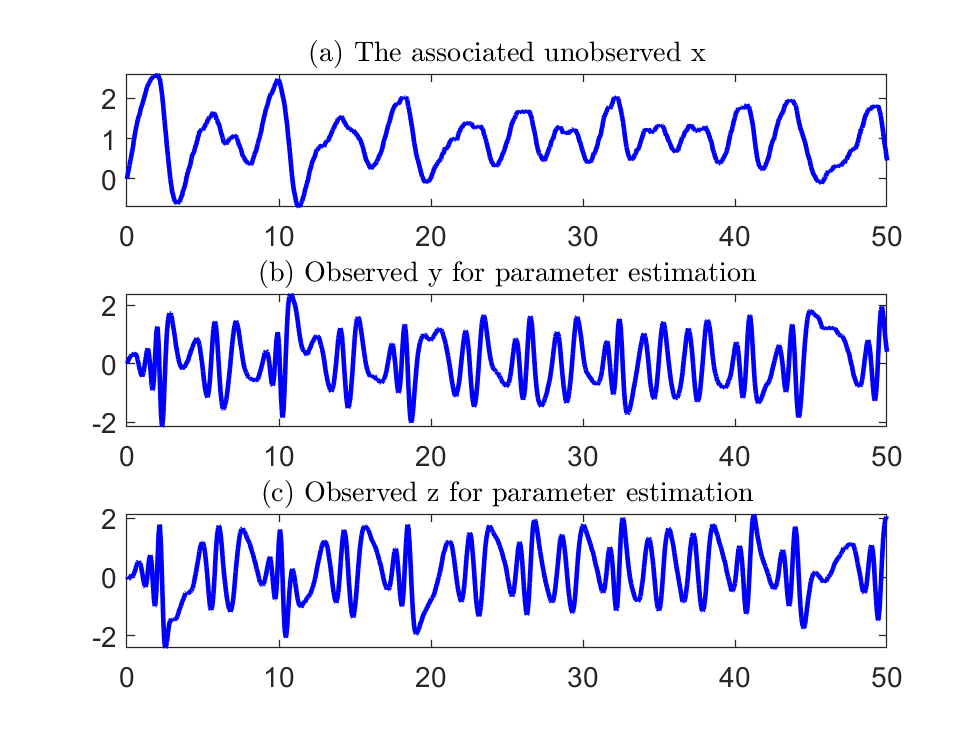

figure
subplot(3,1,1)
plot(dt:dt:N*dt,x_truth,'b','linewidth',2)
box on
set(gca,'fontsize',12)
title('(a) The associated unobserved x','fontsize',12)
xlim([0,50])
subplot(3,1,2)
plot(dt:dt:N*dt,y_truth,'b','linewidth',2)
box on
set(gca,'fontsize',12)
xlim([0,50])
title('(b) Observed y for parameter estimation','fontsize',12)
subplot(3,1,3)
plot(dt:dt:N*dt,z_truth,'b','linewidth',2)
box on
set(gca,'fontsize',12)
title('(c) Observed z for parameter estimation','fontsize',12)
xlim([0,50])

%% initial system
M = 12;

% library order
% 1, y, z, y^2, z^2, yz, x, xy, xz, xy^2, xz^2, xyz

% dx/dt = y^2 - z^2 + 2 + (y^2 - z^2) x
Xi_x = zeros(M,1);
Xi_x(1)  =  2;   % 1
Xi_x(4)  =  1;   % y^2
Xi_x(5)  = -1;   % z^2
Xi_x(10) =  1;   % x*y^2
Xi_x(11) = -1;   % x*z^2

% dy/dt = -y - 2y^2 + z^2 + 1 + (-y - 8z - yz) x
Xi_y = zeros(M,1);
Xi_y(1)  =  1;   % 1
Xi_y(2)  = -1;   % y
Xi_y(4)  = -2;   % y^2
Xi_y(5)  =  1;   % z^2
Xi_y(8)  = -1;   % x*y
Xi_y(9)  = -8;   % x*z
Xi_y(12) = -1;   % x*y*z

% dz/dt = -z + z^2 - yz + (8y + z + z^2) x
Xi_z = zeros(M,1);
Xi_z(3)  = -1;   % z
Xi_z(5)  =  1;   % z^2
Xi_z(6)  = -1;   % y*z
Xi_z(8)  =  8;   % x*y
Xi_z(9)  =  1;   % x*z
Xi_z(11) =  1;   % x*z^2

idx_nonconst = setdiff(1:36, [1 13 25], 'stable'); % 33 entries
Theta0 = [Xi_x; Xi_y; Xi_z];
Smask_0 = Theta0(idx_nonconst) ~= 0;

% build H and g for H*Theta = g
term.one = 1;
term.y = 2;
term.z = 3;
term.y2 = 4;
term.z2 = 5;
term.yz = 6;
term.x = 7;
term.xy = 8;
term.xz = 9;
term.xy2 = 10;
term.xz2 = 11;
term.xyz = 12;

% eq = 1 x, 2 y, 3 z
gid = @(eq, k) (eq-1)*12 + k;

H = zeros(11, 36);
g = zeros(11, 1);

% y^2 in y eq and z^2 in z eq
H(1,gid(2, term.y2)) = 1;
H(2,gid(3, term.z2)) = 1;

% coupled constraints
H(3, gid(1, term.y2)) = 1;
H(3, gid(2, term.xy)) = 1;
H(4, gid(1, term.z2)) = 1;
H(4, gid(3, term.xz)) = 1;
H(5, gid(1, term.yz)) = 1;
H(5, gid(2, term.xz)) = 1;
H(5, gid(3, term.xy)) = 1;

% x^2 y and x^2 z terms
H(6, gid(1, term.xy)) = 1;
H(7, gid(1, term.xz)) = 1;

% mixed quadratic terms
H(8, gid(2, term.yz)) = 1;
H(8, gid(3, term.y2)) = 1;
H(9, gid(2, term.z2)) = 1;
H(9, gid(3, term.yz)) = 1;

H(10, gid(2, term.z)) = 1;
H(11, gid(3, term.y)) = 1;

Theta_truth = L84_theta_from_truth(a_truth, b_truth, f_truth, g_truth);
Smask_truth = Theta_truth(idx_nonconst) ~= 0;

rng(123);
%% main loop
% y and z are observed and x is hidden

y_obs = y_truth(:);
z_obs = z_truth(:);

% hyper-parameters
maxOuterIter = 120;
thrCE = 1e-3;

% initial guesses
Theta_k = Theta0;
sigma_x = sigma_x_truth;
sigma_y = 1;
sigma_z = 1;

% constraints
size(H)

ans =     11    36


size(g)

ans =     11     1



% history
hist = struct();
hist.Theta = zeros(36, maxOuterIter+1);
hist.sig_y = zeros(1,  maxOuterIter+1);
hist.sig_z = zeros(1,  maxOuterIter+1);
hist.mask  = false(33, maxOuterIter+1);   % non-constant mask
hist.x_samp  = zeros(N, maxOuterIter+1);
hist.Thetadiff = zeros(1, maxOuterIter+1);
hist.maskdiff = zeros(1, maxOuterIter+1);

smask_long = Smask_0;

for it = 1:maxOuterIter+1
    fprintf('\n================ iteration %d / %d ================\n', it-1, maxOuterIter);
    fprintf('current sigmas: sigma_x=%.4f (fixed), sigma_y=%.4f, sigma_z=%.4f\n', sigma_x, sigma_y, sigma_z);

    % enkbs update
    [~, ~, ~, ~, xhat] = L84_EnKBS( ...
        dt, N, m_ens, sigma_x^2, sigma_y^2, sigma_z^2, y_obs, z_obs, Theta_k);
    
%     % cgns update
%     [~, ~, ~, ~, xhat] = L84_CGNS_SmootherSampling( ...
%          dt, N, m_ens, sigma_x^2, sigma_y^2, sigma_z^2, y_obs, z_obs, Theta_k);
  
    % record current state
    hist.Theta(:,it)  = Theta_k;
    hist.sig_y(it)    = sigma_y;
    hist.sig_z(it)    = sigma_z;
    hist.x_samp(:,it) = xhat;
    hist.mask(:,it)   = smask_long;

    fprintf(' %d / 33 non-constant terms (thrCE=%.1e)', ...
        nnz(smask_long), thrCE);
    
    fprintf('nonphysical = max(abs(H*Theta-g)) = %.7f\n', max(abs(H*Theta_k-g)));
    
    %% step 2 ce mask
    [smask_long1, ~, ~, ~] = ...
        l84_causation_entropy_mask(xhat, y_obs, z_obs, thrCE);

    %% step 3 mle theta + sigma
    [Theta_k1, sigma_y, sigma_z] = ...
        l84_estimate_theta_sigma(smask_long1, xhat, y_obs, z_obs, dt, sigma_x, H, g);
    
    hist.maskdiff(1,it) = nnz(smask_long ~= smask_long1);
    hist.Thetadiff(1,it) = norm(Theta_k1-Theta_k,inf)/norm(Theta_k,inf);
    
    fprintf('maskdiff = %d\n', hist.maskdiff(1,it));
    fprintf('thetadiff = %.5f\n', hist.Thetadiff(1,it));
    
    smask_long = smask_long1;
    Theta_k = Theta_k1;
end


================ iteration 0 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=1.0000, sigma_z=1.0000


 16 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 2.0000000


maskdiff = 13


thetadiff = 0.53232



================ iteration 1 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1435, sigma_z=0.1479


 17 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 6


thetadiff = 0.41588



================ iteration 2 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1046, sigma_z=0.1051


 13 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.09401



================ iteration 3 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1023, sigma_z=0.1021


 13 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 2


thetadiff = 0.04969



================ iteration 4 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1015, sigma_z=0.1013


 11 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.04959



================ iteration 5 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1010, sigma_z=0.1008


 11 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.04493



================ iteration 6 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1006, sigma_z=0.1006


 11 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.03795



================ iteration 7 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1004, sigma_z=0.1004


 11 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.02875



================ iteration 8 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1003, sigma_z=0.1003


 11 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.02586



================ iteration 9 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1002, sigma_z=0.1001


 11 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 1


thetadiff = 0.05726



================ iteration 10 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1001, sigma_z=0.1001


 10 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 1


thetadiff = 0.09592



================ iteration 11 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1001, sigma_z=0.1001


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.01703



================ iteration 12 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1001


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00919



================ iteration 13 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1001


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00699



================ iteration 14 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00484



================ iteration 15 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00208



================ iteration 16 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00370



================ iteration 17 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00419



================ iteration 18 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00374



================ iteration 19 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00326



================ iteration 20 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00298



================ iteration 21 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00208



================ iteration 22 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00259



================ iteration 23 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00299



================ iteration 24 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00302



================ iteration 25 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00098



================ iteration 26 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00142



================ iteration 27 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00233



================ iteration 28 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00146



================ iteration 29 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00210



================ iteration 30 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00268



================ iteration 31 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00264



================ iteration 32 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00092



================ iteration 33 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00153



================ iteration 34 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00301



================ iteration 35 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00131



================ iteration 36 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00281



================ iteration 37 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00127



================ iteration 38 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00247



================ iteration 39 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00211



================ iteration 40 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00217



================ iteration 41 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00154



================ iteration 42 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00248



================ iteration 43 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00272



================ iteration 44 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00145



================ iteration 45 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00230



================ iteration 46 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00116



================ iteration 47 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00228



================ iteration 48 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00189



================ iteration 49 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00144



================ iteration 50 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00234



================ iteration 51 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00200



================ iteration 52 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00255



================ iteration 53 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00106



================ iteration 54 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00166



================ iteration 55 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00094



================ iteration 56 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00157



================ iteration 57 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00133



================ iteration 58 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00138



================ iteration 59 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00146



================ iteration 60 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00204



================ iteration 61 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00076



================ iteration 62 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00170



================ iteration 63 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00151



================ iteration 64 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00182



================ iteration 65 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00145



================ iteration 66 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00132



================ iteration 67 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00111



================ iteration 68 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00225



================ iteration 69 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00185



================ iteration 70 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00175



================ iteration 71 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00190



================ iteration 72 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00161



================ iteration 73 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00117



================ iteration 74 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00066



================ iteration 75 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00151



================ iteration 76 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00189



================ iteration 77 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00183



================ iteration 78 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00132



================ iteration 79 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00076



================ iteration 80 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00088



================ iteration 81 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00116



================ iteration 82 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00192



================ iteration 83 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00202



================ iteration 84 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00136



================ iteration 85 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00203



================ iteration 86 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00150



================ iteration 87 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00113



================ iteration 88 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00120



================ iteration 89 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00050



================ iteration 90 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00213



================ iteration 91 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00224



================ iteration 92 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00073



================ iteration 93 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00176



================ iteration 94 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00144



================ iteration 95 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00181



================ iteration 96 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00062



================ iteration 97 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00141



================ iteration 98 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00228



================ iteration 99 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00172



================ iteration 100 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00120



================ iteration 101 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00164



================ iteration 102 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00214



================ iteration 103 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00221



================ iteration 104 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00158



================ iteration 105 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00081



================ iteration 106 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00085



================ iteration 107 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00119



================ iteration 108 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00085



================ iteration 109 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00086



================ iteration 110 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00064



================ iteration 111 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00101



================ iteration 112 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00107



================ iteration 113 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00115



================ iteration 114 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00188



================ iteration 115 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00120



================ iteration 116 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00072



================ iteration 117 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00136



================ iteration 118 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00073



================ iteration 119 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00081



================ iteration 120 / 120 ================


current sigmas: sigma_x=0.1000 (fixed), sigma_y=0.1000, sigma_z=0.1000


 9 / 33 non-constant terms (thrCE=1.0e-03)

nonphysical = max(abs(H*Theta-g)) = 0.0000000


maskdiff = 0


thetadiff = 0.00081



nIterDone = it;
fprintf('\ndone. total iterations executed = %d\n', nIterDone-1);


done. total iterations executed = 120


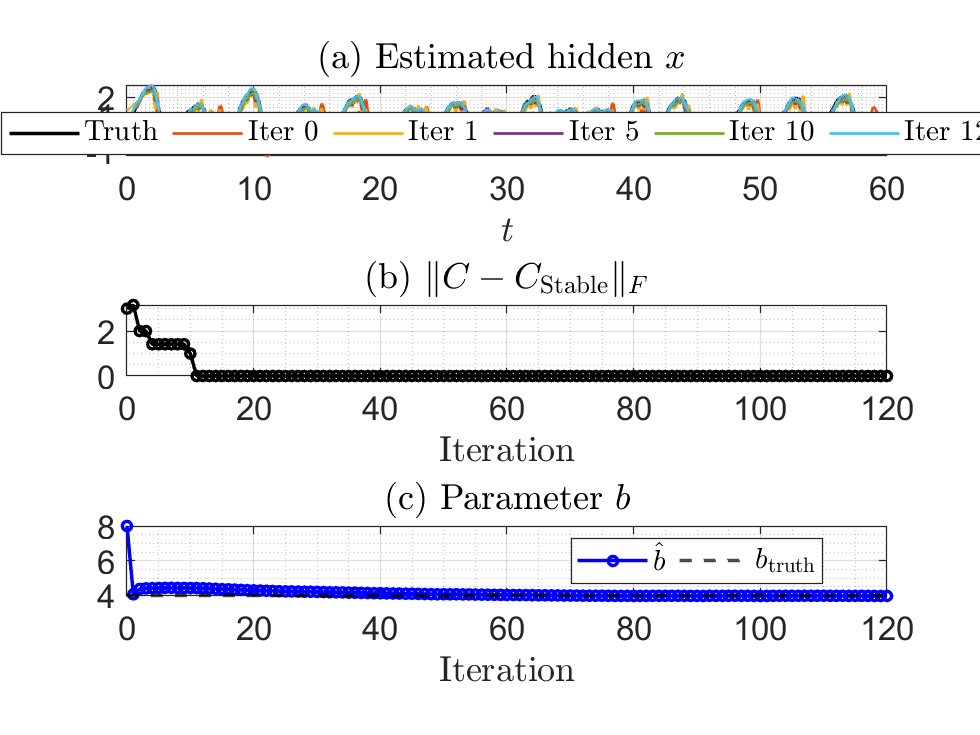

%% plots for learning history

Nt = N;
tt = (0:Nt-1) * dt;

% downsample for plotting
skip_plot = 50;
idx = 1:skip_plot:Nt;
t_plot = tt(idx);

% selected iterations
its_show = 1+[0 1 5 10 120];
its_show = its_show(its_show <= nIterDone);

figure;

%% panel a
subplot(3,1,1); hold on;
plot(t_plot, x_truth(idx), 'k-', 'LineWidth', 1.5);

for k = 1:numel(its_show)
    it_show = its_show(k);
    xk = hist.x_samp(idx, it_show);
    plot(t_plot, xk, 'LineWidth', 1.2);
end

xlim([0, 60]);
box on; grid on; grid(gca,'minor');
set(gca,'fontsize',14);
title(sprintf('(a) Estimated hidden $x$ '), 'Interpreter','latex');
xlabel('$t$', 'Interpreter','latex');

leg = cell(1, 1+numel(its_show));
leg{1} = 'Truth';
for k = 1:numel(its_show)
    leg{1+k} = sprintf('Iter %d', its_show(k)-1);
end
legend(leg, 'Interpreter','latex', 'Location','best', 'Orientation','horizontal');

%% panel b
subplot(3,1,2); hold on;
it_start = 1:nIterDone;

dmask = zeros(1,nIterDone);
Cdiff = zeros(1,nIterDone);
for it = 1:nIterDone
    dmask(it) = nnz(hist.mask(:, it) ~= hist.mask(:, nIterDone));
    Cdiff(it) = sqrt(dmask(it));
end
    
plot(it_start-1, Cdiff, 'k-o', 'LineWidth', 1.5, 'MarkerSize', 4);

box on; grid on; grid(gca,'minor');
set(gca,'fontsize',14);
title('(b) $\|C - C_{\mathrm{Stable}}\|_F$', 'Interpreter','latex');
xlabel('Iteration', 'Interpreter','latex');

%% panel c
subplot(3,1,3); hold on;

bhat = zeros(1,nIterDone);
for it = 1:nIterDone
    theta_y_xz = hist.Theta(gid(2, term.xz),it);
    theta_z_xy = hist.Theta(gid(3, term.xy),it);
    bhat(it) = 0.5 * (-theta_y_xz + theta_z_xy);
end

plot(it_start-1, bhat(it_start), 'b-o', 'LineWidth', 1.5, 'MarkerSize', 4);
yline(b_truth, 'k--', 'LineWidth', 1.5);

box on; grid on; grid(gca,'minor');
set(gca,'fontsize',14);
title('(c) Parameter $b$', 'Interpreter','latex');
xlabel('Iteration', 'Interpreter','latex');
legend('$\hat b$', '$b_{\mathrm{truth}}$', 'Interpreter','latex', 'Location','best', 'Orientation','horizontal');

%% final nonzero mask and Theta values
Smask_final = smask_long(:);
Theta_final = Theta_k(:);
idx_nonconst = setdiff(1:36, [1 13 25], 'stable');

idx_keep33 = find(Smask_final);
idx_theta  = idx_nonconst(idx_keep33);
vals_theta = Theta_final(idx_theta);

fprintf('\nfinal identified nonzero Smask = %d / 33 terms\n', numel(idx_keep33));


final identified nonzero Smask = 9 / 33 terms


for k = 1:numel(idx_keep33)
    fprintf('  smask(%2d)=1  ->  Theta(%2d) = %+ .4f\n', idx_keep33(k), idx_theta(k), vals_theta(k));
end

  smask( 3)=1  ->  Theta( 4) = -1.0023
  smask( 4)=1  ->  Theta( 5) = -1.0011
  smask( 6)=1  ->  Theta( 7) = -0.2458
  smask(12)=1  ->  Theta(14) = -1.0135
  smask(18)=1  ->  Theta(20) = +1.0023
  smask(19)=1  ->  Theta(21) = -3.9732
  smask(24)=1  ->  Theta(27) = -1.0037
  smask(29)=1  ->  Theta(32) = +3.9732
  smask(30)=1  ->  Theta(33) = +1.0011



% false positives and false negatives against truth
fp = find(Smask_final & ~Smask_truth);
fn = find(~Smask_final & Smask_truth);

fprintf('\nfalse positives = %d\n', numel(fp));


false positives = 0


for k = 1:numel(fp)
    j = fp(k);
    fprintf('  FP: smask(%2d)=1 -> Theta(%2d)=%+ .6e\n', j, idx_nonconst(j), Theta_final(idx_nonconst(j)));
end

fprintf('\nfalse negatives = %d\n', numel(fn));


false negatives = 0


for k = 1:numel(fn)
    j = fn(k);
    fprintf('  FN: smask(%2d)=0 -> Theta_truth(%2d)=%+ .6e\n', j, idx_nonconst(j), Theta_truth(idx_nonconst(j)));
end

%% selected parameters

Theta_id = Theta_k(:);

term.one = 1;
term.y   = 2;
term.z   = 3;
term.y2  = 4;
term.z2  = 5;
term.yz  = 6;
term.x   = 7;
term.xy  = 8;
term.xz  = 9;

gid = @(eq, k) (eq-1)*12 + k;

paramNames = { ...
    'theta_x_x', 'theta_y_y', 'theta_z_z', 'theta_x_yy', 'theta_x_zz', 'theta_y_xz', ...
    'theta_y_xy','theta_z_xy','theta_z_xz','theta_x_1', 'theta_y_1', 'theta_z_1'};

idxPick = [ ...
    gid(1,term.x),  gid(2,term.y),  gid(3,term.z), ...
    gid(1,term.y2), gid(1,term.z2), gid(2,term.xz), ...
    gid(2,term.xy), gid(3,term.xy), gid(3,term.xz), ...
    gid(1,term.one),gid(2,term.one),gid(3,term.one) ];

TruthVals = Theta_truth(idxPick).';
IdVals    = Theta_id(idxPick).';

T = array2table([TruthVals; IdVals], ...
    'RowNames', {'Truth','Identified'}, ...
    'VariableNames', matlab.lang.makeValidName(paramNames));

disp('Table 1 (Truth vs Identified):');

Table 1 (Truth vs Identified):


disp(T)

                  theta_x_x    theta_y_y    theta_z_z    theta_x_yy    theta_x_zz    theta_y_xz    theta_y_xy    theta_z_xy    theta_z_xz    theta_x_1    theta_y_1    theta_z_1 
                  _________    _________    _________    __________    __________    __________    __________    __________    __________    _________    _________    __________

    Truth            -0.25           -1           -1           -1            -1            -4             1             4             1            2            1               0
    Identified    -0.24

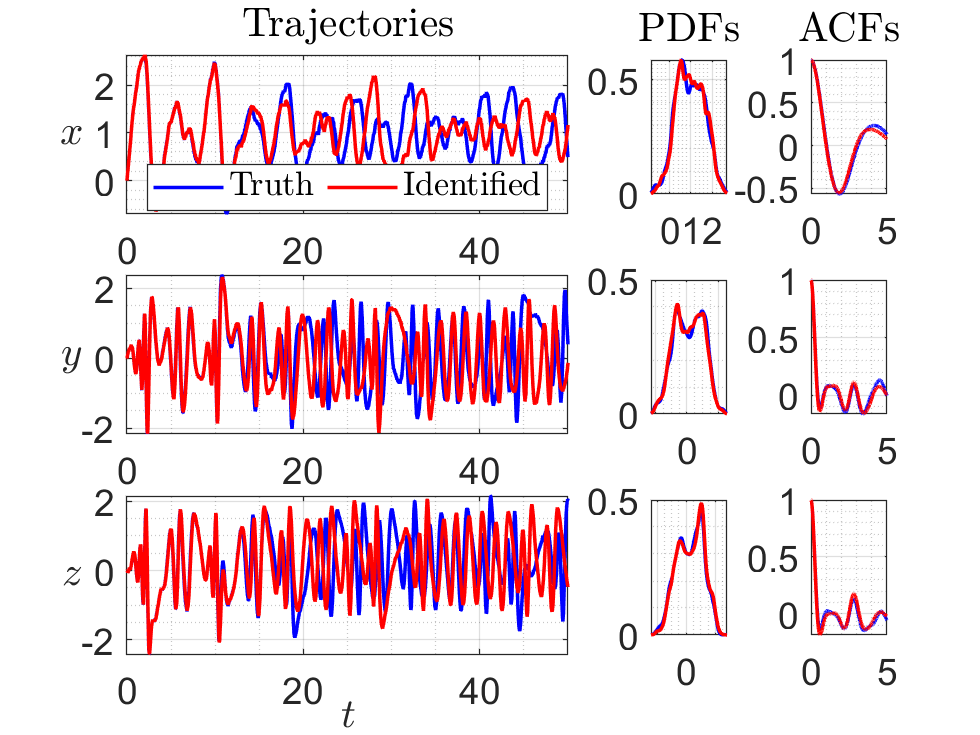

%% truth vs identified trajectories statistics

Theta_truth = L84_theta_from_truth(a_truth, b_truth, f_truth, g_truth);

Tshow = 50;
Nt_show = min(N, round(Tshow/dt));

x0 = x_truth(1);
y0 = y_truth(1);
z0 = z_truth(1);

% same noise increments for both systems
rng(123);
dW = sqrt(dt) * randn(3, N-1);

sig_truth = [sigma_x_truth; sigma_y_truth; sigma_z_truth];
sig = [sigma_x_truth; hist.sig_y(1,nIterDone); hist.sig_z(1,nIterDone)];

[X_true, Y_true, Z_true] = L84_sim_theta_same_noise(dt, N, Theta_truth, sig_truth, x0, y0, z0, dW);

Theta_id = hist.Theta(:, nIterDone);
[X_id,   Y_id,   Z_id] = L84_sim_theta_same_noise(dt, N, Theta_id, sig, x0, y0, z0, dW);

tt = (0:N-1)*dt;
useIdx  = 1:N;

maxLagTime = 5;
maxLag = round(maxLagTime/dt);
lags_t = (0:maxLag)*dt;

% use autocorr if available
use_autocorr = (exist('autocorr','file')==2);

figure;
set(gca,'fontsize',16);

% row 1 x
subplot(3,5,1:3); hold on;
plot(tt(1:Nt_show), X_true(1:Nt_show), 'b-', 'LineWidth', 1.5);
plot(tt(1:Nt_show), X_id(1:Nt_show),   'r-', 'LineWidth', 1.5);
box on; grid on; grid(gca,'minor');
title('Trajectories', 'Interpreter','latex');
yl=ylabel('$x$', 'Interpreter','latex');
set(yl,'Rotation',0);
yl.Units = 'normalized';
yl.Position(1) = -0.10;
yl.Position(2) = 0.5;
yl.HorizontalAlignment = 'right';
yl.VerticalAlignment   = 'middle';
legend('Truth','Identified','Location','best','Orientation','horizontal'); xlim([0, Tshow]);
set(gca,'fontsize',16);

subplot(3,5,4); hold on;
xT = X_true(useIdx); xI = X_id(useIdx);
xgrid = linspace(min([xT(:);xI(:)]), max([xT(:);xI(:)]), 200);
pT = ksdensity(xT, xgrid);
pI = ksdensity(xI, xgrid);
plot(xgrid, pT, 'b-', 'LineWidth', 1.5);
plot(xgrid, pI, 'r-', 'LineWidth', 1.5);
box on; grid on; grid(gca,'minor');
title('PDFs', 'Interpreter','latex');
set(gca,'fontsize',16);

subplot(3,5,5); hold on;
if use_autocorr
    [acfT, lags] = autocorr(xT, 'NumLags', maxLag);
    [acfI, ~]    = autocorr(xI, 'NumLags', maxLag);
    lags_t = lags(:)*dt;
else
    [acfT, lags] = acf_formula21(xT, maxLag);
    [acfI, ~]    = acf_formula21(xI, maxLag);
    lags_t = lags * dt;
end
plot(lags_t, acfT, 'b-', 'LineWidth', 1.5);
plot(lags_t, acfI, 'r-', 'LineWidth', 1.5);
box on; grid on; grid(gca,'minor');
title('ACFs', 'Interpreter','latex');
xlim([0, maxLagTime]);set(gca,'fontsize',16);

% row 2 y
subplot(3,5,6:8); hold on;
plot(tt(1:Nt_show), Y_true(1:Nt_show), 'b-', 'LineWidth', 1.5);
plot(tt(1:Nt_show), Y_id(1:Nt_show),   'r-', 'LineWidth', 1.5);
box on; grid on; grid(gca,'minor');
yl=ylabel('$y$', 'Interpreter','latex');
set(yl,'Rotation',0);
yl.Units = 'normalized';
yl.Position(1) = -0.10;
yl.Position(2) = 0.5;
yl.HorizontalAlignment = 'right';
yl.VerticalAlignment   = 'middle';
xlim([0, Tshow]);set(gca,'fontsize',16);

subplot(3,5,9); hold on;
yT = Y_true(useIdx); yI = Y_id(useIdx);
ygrid = linspace(min([yT(:);yI(:)]), max([yT(:);yI(:)]), 200);
pT = ksdensity(yT, ygrid);
pI = ksdensity(yI, ygrid);
plot(ygrid, pT, 'b-', 'LineWidth', 1.5);
plot(ygrid, pI, 'r-', 'LineWidth', 1.5);
box on; grid on; grid(gca,'minor');set(gca,'fontsize',16);

subplot(3,5,10); hold on;
if use_autocorr
    [acfT, lags] = autocorr(yT, 'NumLags', maxLag);
    [acfI, ~]    = autocorr(yI, 'NumLags', maxLag);
    lags_t = lags(:)*dt;
else
    [acfT, lags] = acf_formula21(yT, maxLag);
    [acfI, ~]    = acf_formula21(yI, maxLag);
    lags_t = lags * dt;
end
plot(lags_t, acfT, 'b-', 'LineWidth', 1.5);
plot(lags_t, acfI, 'r-', 'LineWidth', 1.5);
box on; grid on; grid(gca,'minor');
xlim([0, maxLagTime]);set(gca,'fontsize',16);

% row 3 z
subplot(3,5,11:13); hold on;
plot(tt(1:Nt_show), Z_true(1:Nt_show), 'b-', 'LineWidth', 1.5);
plot(tt(1:Nt_show), Z_id(1:Nt_show),   'r-', 'LineWidth', 1.5);
box on; grid on; grid(gca,'minor');
xl = xlabel('$t$','Interpreter','latex');
xl.Units = 'normalized';
xl.Position(2) = -0.25;

yl=ylabel('$z$', 'Interpreter','latex');
yl.Units = 'normalized';
yl.Position(1) = -0.10;
yl.Position(2) = 0.5;
yl.HorizontalAlignment = 'right';
yl.VerticalAlignment   = 'middle';
set(yl,"Rotation",0)
xlim([0, Tshow]);set(gca,'fontsize',16);

subplot(3,5,14); hold on;
zT = Z_true(useIdx); zI = Z_id(useIdx);
zgrid = linspace(min([zT(:);zI(:)]), max([zT(:);zI(:)]), 200);
pT = ksdensity(zT, zgrid);
pI = ksdensity(zI, zgrid);
plot(zgrid, pT, 'b-', 'LineWidth', 1.5);
plot(zgrid, pI, 'r-', 'LineWidth', 1.5);
box on; grid on; grid(gca,'minor');set(gca,'fontsize',16);

subplot(3,5,15); hold on;
if use_autocorr
    [acfT, lags] = autocorr(zT, 'NumLags', maxLag);
    [acfI, ~]    = autocorr(zI, 'NumLags', maxLag);
    lags_t = lags(:)*dt;
else
    [acfT, lags] = acf_formula21(zT, maxLag);
    [acfI, ~]    = acf_formula21(zI, maxLag);
    lags_t = lags * dt;
end
plot(lags_t, acfT, 'b-', 'LineWidth', 1.5);
plot(lags_t, acfI, 'r-', 'LineWidth', 1.5);
box on; grid on; grid(gca,'minor');
xlim([0, maxLagTime]);set(gca,'fontsize',16);